# Check Productive Structure

#### Get the Processes Adjacency Matrix

Build the extended (S,T) adjacency matrix

data=ReadDataModel('cgam_model.json');
ps=data.ProductiveStructure;
N=ps.NrOfProcesses;
S=1;T=N+2;
nodeNames=['S',ps.ProcessKeys(1:N),'T'];
mFP=ps.ProcessMatrix;
sources = mFP(end,1:end-1);
outputs = mFP(1:end-1,end);
internal = mFP(1:end-1,1:end-1);
A=[0 sources 0; zeros(N,1) internal outputs;zeros(1,T)];

#### Plot Processes Graph

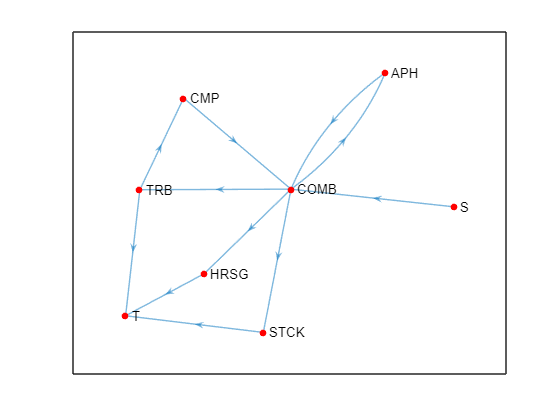

dg=digraph(A,nodeNames);
plot(dg,'NodeColor','red')

#### Check Source-Sink connectivity

D=transitiveClosure(A);
sol = all(D(S,:)) & all(D(:,T));
fprintf('Productive graph: %s', mat2str(sol));

Productive graph: true